# E3DSB miniprojekt 3 – Tone Control 

Team 4

202200284 - Danni Raetzel

201900368 - Martin Armose

### **Indledning og formål**

Denne rapport fokuserer på udviklingen af et digitalt shelving-filter, der er implementeret i MATLAB. Shelving-filtre anvendes ofte i audioeffekter til at justere frekvensresponsen ved at forstærke eller dæmpe bestemte frekvensområder.

I rapporten beskrives implementeringen af et andetordens shelving-filter med vores egen brugerdefineret MATLAB-funktion. Vi sammenligner resultaterne fra vores egen filterfunktion, med MATLAB's indbyggede filterfunktion. 

Målet med rapporten er at demonstrere forståelsen af digital filtrering og evaluere implementeringen af et IIR-filter i en praktisk kontekst.

[Zölzer, U. *DAFX: Digital Audio Effects*. 2. udgave, John Wiley & Sons, kapitel 2.3.]

### Delopgaver

#### a)

**Input værdier**

% Læs lydfilen
[x, fs] = audioread('03 When It Comes To You_11s (1).wav');  % Indlæs lydfilen
t = (0:length(x)-1)/fs;         % Tidsvektor på lydfilens længde

% Bas
gain_bass = 4% Gain Bas dB

gain_bass = 4

fc_bass = 2860% Cutoff frekvens Bas Hz

fc_bass = 2860


% Treble eller diskant
gain_treble = -2% Gain treble dB

gain_treble = -2

fc_treble = 16740% Cutoff frekvens treble Hz

fc_treble = 16740

**Second-order shelving filter design**

Vi laver vores egen shelving filter funktion, ved at indhente koefficienterne fra tabeller.

% Shelving filter med separate bas- og diskantparametre
function [b_bass, a_bass, b_treble, a_treble] = shelving2ndOrder(gain_bass, fc_bass, gain_treble, fc_treble, fs)
    % Bass filter (LF Boost)
    K_bass = tan(pi * fc_bass / fs);     % Ref: Zölzer, U., *DAFX*, s. 64, tabel 2.3.
    V0_bass = 10^(gain_bass / 20);       % Ref: Zölzer, U., *DAFX*, s. 64, tabel 2.3.
    lfb_den = (1 + sqrt(2)*K_bass + K_bass^2);
    b_bass = [(1 + sqrt(2*V0_bass)*K_bass + V0_bass*K_bass^2) / lfb_den, (2*(V0_bass*K_bass^2 - 1)) / lfb_den, (1 - sqrt(2*V0_bass)*K_bass + V0_bass*K_bass^2) / lfb_den];
    a_bass = [1, (2*(K_bass^2 - 1)) / lfb_den, (1 - sqrt(2)*K_bass + K_bass^2) / lfb_den];
    
    % Normaliser bass filter
    b_bass = b_bass / a_bass(1);
    a_bass = a_bass / a_bass(1);

    % Treble filter (HF Boost)
    K_treble = tan(pi * fc_treble / fs); % Ref: Zölzer, U., *DAFX*, s. 64, tabel 2.3.
    V0_treble = 10^(gain_treble / 20);   % Ref: Zölzer, U., *DAFX*, s. 64, tabel 2.3.
    hfb_den = (1 + sqrt(2)*K_treble + K_treble^2);
    b_treble = [(V0_treble + sqrt(2*V0_treble)*K_treble + K_treble^2) / hfb_den, (2*(K_treble^2 - V0_treble)) / hfb_den, (V0_treble - sqrt(2*V0_treble)*K_treble + K_treble^2) / hfb_den];
    a_treble = [1, (2*(K_treble^2 - 1)) / hfb_den, (1 - sqrt(2)*K_treble + K_treble^2) / hfb_den];

    % Normaliser treble filter
    b_treble = b_treble / a_treble(1);
    a_treble = a_treble / a_treble(1);
end

#### Test af funktionen

% Beregn filterkoefficienter
[b_bass, a_bass, b_treble, a_treble] = shelving2ndOrder(gain_bass, fc_bass, gain_treble, fc_treble, fs)

b_bass =     1.0754   -1.3969    0.5243


a_bass =     1.0000   -1.4343    0.5622


b_treble =     0.9456    1.0169    0.3631


a_treble =     1.0000    0.9792    0.3465


#### b)

% iir2df1: et 2. ordens IIR-filter i Direct Form I med kaskade
% Lyons, R. *Understanding Digital Signal Processing*. Pearson, kapitel 6.8.1.
function y = iir2df1(b1, a1, b2, a2, x)
  
    N = length(x);           % Længden af inputsignalet
    y1 = zeros(1, N);        % Outputsignal efter første filter
    y = zeros(1, N);         % Endeligt outputsignal efter begge filtre

    % Initialiser forsinkede værdier for første filter (x1(n-1), x1(n-2), y1(n-1), y1(n-2))
    x1_1 = 0; x1_2 = 0;      % Forsinkede inputværdier til første filter
    y1_1 = 0; y1_2 = 0;      % Forsinkede outputværdier til første filter

    % Første filter anvendt på inputsignal
    for n = 1:N
        % Nuværende input x(n)
        xn = x(n);
        
        % Differensligning for første filter
        yn1 = b1(1)*xn + b1(2)*x1_1 + b1(3)*x1_2 - a1(2)*y1_1 - a1(3)*y1_2;
        
        % Gemmer output y1(n)
        y1(n) = yn1;
        
        % Opdaterer forsinkede værdier for første filter
        x1_2 = x1_1;
        x1_1 = xn;
        y1_2 = y1_1;
        y1_1 = yn1;
    end

    % Initialiser forsinkede værdier for andet filter (x2(n-1), x2(n-2), y2(n-1), y2(n-2))
    x2_1 = 0; x2_2 = 0;      % Forsinkede inputværdier til andet filter
    y2_1 = 0; y2_2 = 0;      % Forsinkede outputværdier til andet filter

    % Andet filter anvendt på output fra første filter
    for n = 1:N
        % Nuværende input til andet filter er output fra første filter y1(n)
        xn2 = y1(n);
        
        % Differensligning for andet filter
        yn2 = b2(1)*xn2 + b2(2)*x2_1 + b2(3)*x2_2 - a2(2)*y2_1 - a2(3)*y2_2;
        
        % Gem endeligt output y(n)
        y(n) = yn2;
        
        % Opdater forsinkede værdier for andet filter
        x2_2 = x2_1;
        x2_1 = xn2;
        y2_2 = y2_1;
        y2_1 = yn2;
    end
end


**Test af funktionen**

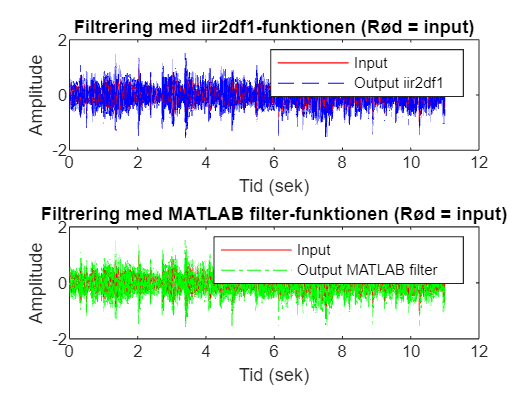

% Anvender den tilpassede iir2df1-funktion med kaskaderede filtre
y_custom = iir2df1(b_bass, a_bass, b_treble, a_treble, x);

% Bruger MATLAB's indbyggede filter-funktion to gange for kaskaderede filtre
y_builtin = filter(b_treble, a_treble, filter(b_bass, a_bass, x));


% Opretter en figur med to subplots
figure;

% Første subplot: Viser output fra iir2df1-funktion
subplot(2,1,1);  % 2 rækker, 1 kolonne, 1. subplot
plot(t, x, 'r'); hold on;
plot(t, y_custom, 'b--');  % Output fra vores egen funktion
title('Filtrering med iir2df1-funktionen (Rød = input)');
xlabel('Tid (sek)');
ylabel('Amplitude');
legend('Input', 'Output iir2df1');

% Andet subplot: Viser output fra MATLAB's filter-funktion
subplot(2,1,2);  % 2 rækker, 1 kolonne, 2. subplot
plot(t, x, 'r'); hold on;
plot(t, y_builtin, 'g-.');  % Output fra MATLABs indbyggede filter
title('Filtrering med MATLAB filter-funktionen (Rød = input)');
xlabel('Tid (sek)');
ylabel('Amplitude');
legend('Input', 'Output MATLAB filter');


% Zölzer, U., *DAFX: Digital Audio Effects*, s. 47-79, kapitel 2, for teorien om frekvensrespons.

Begge funktioner testes med de samme filterkoefficienter og det samme inputsignal. Resultatet af sammenligningen viser, at de to funktioner giver identiske output. Det var også forventeligt eftersom at vi gerne skulle bruge de samme koefficienter i vores brugerdefinerede funktion, der er med til at definere et shelving filter, som matlab bruger i dens indbyggede filterfunktion.

#### c)

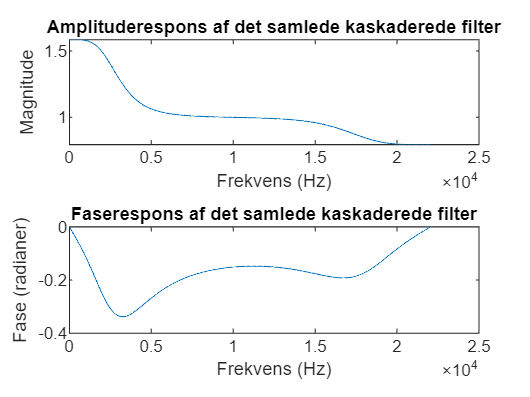

% Beregn filterkoefficienter for kaskaderet filter (kombiner bas og diskant)
[b_samlet, a_samlet] = shelving2ndOrder(gain_bass, fc_bass, gain_treble, fc_treble, fs);
% Beregn frekvensresponsen for det samlede kaskaderede filter
% Vi bruger matlabs freqz til at beregne frekvensresponset

[H, f] = freqz(conv(b_bass, b_treble), conv(a_bass, a_treble), 1024, fs);

% Plot frekvensresponsen
figure;

% Amplituderespons
subplot(2,1,1);
plot(f, abs(H));
title('Amplituderespons af det samlede kaskaderede filter');
xlabel('Frekvens (Hz)');
ylabel('Magnitude');

% Faserespons
subplot(2,1,2);
plot(f, angle(H));
title('Faserespons af det samlede kaskaderede filter');
xlabel('Frekvens (Hz)');
ylabel('Fase (radianer)');


b_samlet = conv(b_bass, b_treble);
a_samlet = conv(a_bass, a_treble);

[H, f] = freqz(b_samlet, a_samlet, 1024, fs);
% Ref: Lyons, R., *Understanding Digital Signal Processing*, kapitel 5.5 og 6.7.

#### d)

% Filtrér lydfilen gennem de kaskaderede filtre
y_filtered = iir2df1(b_bass, a_bass, b_treble, a_treble, x);

% Zölzer, U., *DAFX: Digital Audio Effects*, 2. udgave, John Wiley & Sons, kapitel 2.3.

% Afspiller den originale lyd
%sound(x, fs);

% Afspil den filtrerede lyd
sound(y_filtered, fs);

% Gemmer den filtrerede lyd som en ny fil, til senere aflytning.
audiowrite('filtered_music.wav', y_filtered, fs);

#### Kommentar

- **Basforstærkning/dæmpning**: Når vi satte en lav (negativ) gain på bassen, blev de lave frekvenser dæmpet, og lyden lød "tyndere". Omvendt, når vi hævede gain på bassen, blev bassen dybere og mere fyldig.

- **Diskantforstærkning/dæmpning**: Med høj (positiv) gain på diskanten blev de høje toner skarpere og mere fremtrædende. Ved at sætte en lav gain i diskantområdet blev de høje frekvenser dæmpet, hvilket gav en mere "mørk" og blød lyd.

- **Knækfrekvenser**: Justering af knækfrekvensen påvirkede også lyden markant. En lav knækfrekvens på bassen fokuserede dæmpningen på de helt lave toner, mens en højere knækfrekvens også dæmpede mellemtonerne. I diskanten gjorde en høj knækfrekvens, at kun de højfrekvente lyde blev påvirket, mens en lavere knækfrekvens gav en lysere og mere åben lyd.

### Konklusion

I vores projekt har vi lavet og testet et digitalt shelving-filter i MATLAB, hvor et bas- og diskantfilter blev implementeret som kaskaderede filtre. Vi implementerede en brugerdefineret IIR-funktion (`iir2df1`) og sammenlignede resultaterne med MATLAB's indbyggede `filter`-funktion. Sammenligningen viste, at vores egen filterfunktion svarer til matlabs indbyggede funktion

Vi afprøvede filterfunktionerne med forskellige gain og cutoff frekvenser, som viste at det i praksis kunne lade sig gøre at dæmpe eller forstærke hhv. bas og diskant. 

[Zölzer, U., *DAFX: Digital Audio Effects*, 2. udgave, John Wiley & Sons, kapitel 2.3. Lyons, R., *Understanding Digital Signal Processing*, Pearson.]